# Fundamentos de Matlab Sesión 3-2

## ***Declaración de arreglos de más de dos dimensiones en Matlab.***

En Matlab los arreglos multidimensionales son arreglos de mas de dos dimensiones y se reprepresentan como páginas de un arreglo de la dimensión anterior.

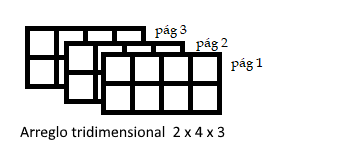

La imágen muestra un arreglo 3D  de dimensiones  2 X 4 x 3 confeccionado a partir de un arreglo bidimencional de 2 x 4 con 3 páginas.

La forma de declarar arreglos multidemensionales en Matlab es agregando páginas a arreglos declarados anteriormente.

**Ejemplo 1  cree un arreglo de 3X3X3 y asígnelo a la variabla A**

- cree cada una de las páginas del arreglo de manera independiente.

- Asigne  al arreglo creado una página a la vez,

La sentencia es **A(:,:,*****númeropágina*****),** aquí *númeropágina* es el indice de la página que se va agregar. Por defecto todos los arreglos bidimensionales en Matlab tienen implicito en indice de página 1.

A1 = [32 8 23;19 17 14; 18 21 13]; % se crea primer arreglo
A2 = [27 12 24;4 23 4;9 5 22];     % segundo arreglo
A3 = [3 56 2; 23 34 76; 8 7 1];    % tercer arreglo
A = A1;                            % A1 asignado a la primera página de A
A(:,:,2) = A2;                     % Se asigna A2 a la segunda página
A(:,:,3) = A3                      % Se asigna A3 a la tercera página y se completa el arreglo

Se puede agregar páginas a un arreglo bidimensional para crear arreglos 3D,  tambien se pueden  crear arreglos multidimensionales, pero este tema hace parte de un curso mas avanzado. Si requiere mayor información visite:

[https://la.mathworks.com/help/matlab/math/multidimensional-arrays.html](https://la.mathworks.com/help/matlab/math/multidimensional-arrays.html)

## Operaciones con Arreglos y con Matrices:

### Operaciones  Aritméticas

Recordemos que Matlab trabaja las matrices como Arreglos númericos bidimensiones cuyas operaciones se rigen por las reglas  del algebra lineal.

De esta forma, Matlab dispone de dos tipos de operaciones aritméticas: 

- Operaciones aitméticas con Arreglos (La operación se hace elemento a elemento y admiten arreglos multidimensionales)

- Operaciones aritméticas con Matrices (Operaciones basadas en algebra lineal).

Cuando la operación es con arreglos en  Matlab se  utiza el operador ***punto (.) ***antes del signo de la operación a realizar, así se indica al procesador que debe operar elemento a elemento entre los arreglos operandos. 

El operador de punto **NO** se usa en el caso de las operaciones de suma (+) y resta (-) ya que éstas se hacen del mismo modo en los dos casos. 

**Ejemplo 2**. si :

`A = `

`     3     4     5`

`     3     6     0`

`b = 3.3`

C = b .* A  resulta en :

`C = `

`    9.9  13.2   16.5`

`    9.9   19.8  0`

#### Operaciones aritméticas  con Arreglos.

La siguiente tabla resume los principales operadores  y operaciones aritméticos  para arreglos en Matlab:

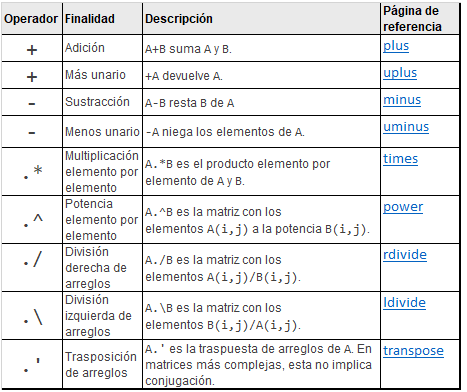

Recuperada de: [https://www.la.mathworks.com](https://la.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html#:~:text=MATLAB%C2%AE%20tiene%20dos%20tipos,potencia%20o%20multiplicar%20dos%20matrices.)

Dado que las operaciones con arreglos se realizan elemento a elemento se hace necesario que los arreglos tengan dimensiones compatibles, en algunos casos Matlab ***expande ***de manera implicita uno de los  dos operandos según sea necesario para hacer compatibles sus dimensiones,  esto  siempre y cuando la expansión pueda realizarse siguiendo alguna de las siguientes reglas:

- *La operación de un escalar  con un arreglo ****n x m**** da como resultado un arreglo**** n x m***

- *La operación de dos arreglos del mismo tamaño da como resutado un arreglo del mismo tamaño.*

- *La operación de una matriz**** n x m****  con un vector columna que tenga el mismo número de filas da como resultado una matriz **** n x m*** 

- *La operación de un vector fila  ****1 x n****  con un vector columna de**** m x 1**** resulta en una matriz ****m x n***

- *La operación entre una matriz ****n x m**** y un arreglo ****n x m x p ****resulta un arreglo ****n x m x p***

        Para más Informacion en sobre compatibilidad de tamaños de los arreglos visite:

 [https://la.mathworks.com/help/matlab/matlab_prog/compatible-array-sizes-for-basic-operations.html](https://la.mathworks.com/help/matlab/matlab_prog/compatible-array-sizes-for-basic-operations.html)

#### Operaciones ariméticas para Matrices:

Las operaciones con matrices siguen las reglas del algebra lineal y sus operandos no pueden ser multidimensionales. la siguiente tabla muestra un resúmen de los operadores aritméticos para matrices en Matlab.

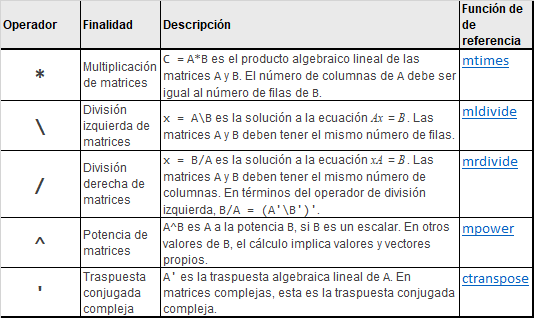

Recuperada de: [https://www.la.mathworks.com](https://la.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html#:~:text=MATLAB%C2%AE%20tiene%20dos%20tipos,potencia%20o%20multiplicar%20dos%20matrices.)

### Operaciones Lógicas y Relacionales

Matlab puede realizar operaciones logicas y de relación enttre arreglos de cualquier dimensión. El resultado de cualquier expresión que involucre operadores lógicos o relacionales es siempre de tipo *logical.* Matlab expresa la condición lógica  **TRUE **(*Verdadero*) con el valor **1** y la condición lógica **FALSE (***Falso***) **con el valor **0. **Si los operandos tienen diferente dimensión, se siguen las mismas reglas compatibilidad de dimensiones descritas anteriormente. Matlab expande igualmente los arreglos si es necesario:

**ejemplo: **

A = 0:5
B = (1:7)'
C = A & B

La siguiente Tabla muestra los operadores logicos y relacionales existentes en $MATLAB ^{R$

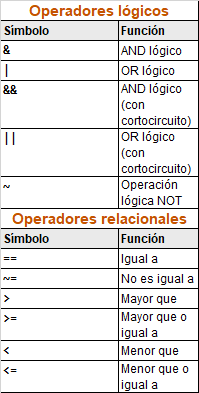

Recuperado de : [https://www.la.mathworks.com](https://la.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html)

Hay que tener muy en cuenta que para Matlab ***"Todo número diferente de 0 (cero) es considerado con valor logico 1 (uno) cuando sobre él se ejecuta una operación lógica o relacional", ***y también que* "****las operaciones lógicas y relacionales se hacen elemento a elemento de los arreglos.***

ejemplo:


A = magic (4)
B = diag(diag (A))
D = A>B
